# **Final Work**

# **Robotics, Kinematics, Dynamics and Control **

**Author: Ilyass Afkir**

**Date: 09.01.2022**

## **0) Introduction**

Initialization of this script.

clear; 
clc; 
warning off;

The following figure shows an antromphoric arm with a spherical wrist with the frames and link lenghts. Note that the base frame is the same as the frame x0,y0,z0.

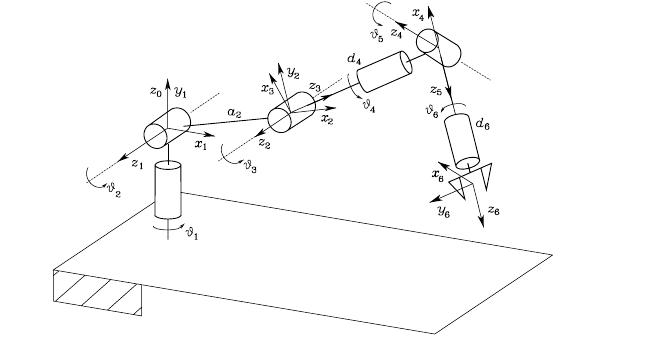

## 1) Compute the DH parameters. Set numerical values to the link lengths and link offsets.

The following tables are showing the DH parameters of the antromphoric arm with a spherical wrist and the numerical values. The link lenghts are in meters and the angles in radiant.

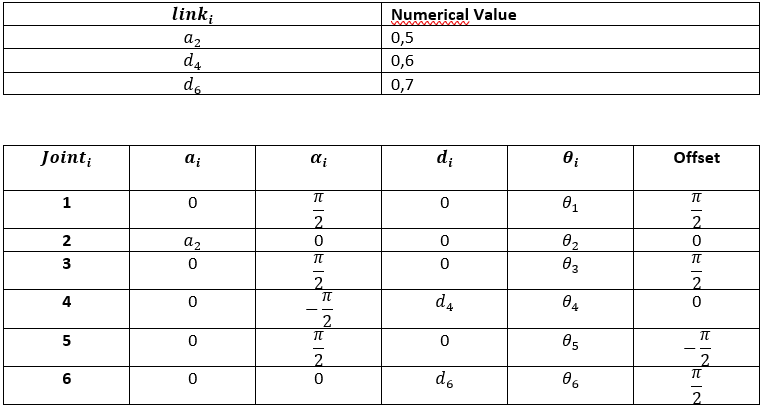

% define link lenghts (meters)
a2 = 0.5;
d4 = 0.6;
d6 = 0.7; 
% define angles (radiant)
alpha1 = pi/2; 
alpha3 = pi/2; 
alpha4 = -pi/2;
alpha5 = pi/2; 

% DH paramters
L(1) = Revolute('alpha', alpha1, 'offset', pi/2);
L(2) = Revolute('a', a2);
L(3) = Revolute('alpha', alpha3, 'offset', pi/2);
L(4) = Revolute('d', d4,'alpha', alpha4);
L(5) = Revolute('alpha', alpha5, 'offset', -pi/2);
L(6) = Revolute('d', d6, 'offset', pi/2);
L;

The following code section displays the table of DH paramters with the defined offsets.

Robot = SerialLink(L, 'name', 'MyRobot')

 
Robot = 
 
MyRobot:: 6 axis, RRRRRR, stdDH, slowRNE                         
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|     1.5708|
|  2|         q2|          0|        0.5|          0|          0|
|  3|         q3|          0|          0|     1.5708|     1.5708|
|  4|         q4|        0.6|          0|    -1.5708|          0|
|  5|         q5|          0|          0|     1.5708|    -1.5708|
|  6|         q6|        0.7|          0|          0|     1.5708|
+---+-----------+-----------+-----------+-----------+-----------+
 


The next code section displays the Robot itself plotted at [0,0,0,0,0,0].

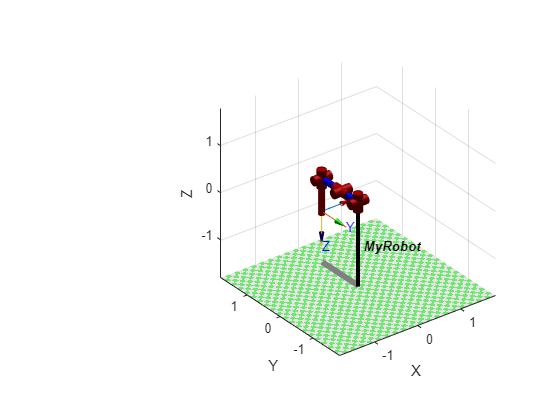

Robot.plot([0,0,0,0,0,0])
Robot.teach

## 2) With the aid of the Symbolic Toolbox:

### (a) Implement a script/function to compute the Forward Kinematics.

First the joint varibles have to be defined.

%joint variables
syms qi q1 q2 q3 q4 q5 q6 as real
syms a2 d4 d6 as real
syms alpha1 alpha3 alpha4 alpha5 as real

The** Forward Kinematics** A matrices will be computed with the ***forward_kin()*** function which is programed in the **Appendix** chapter at end of this file.

% a d alpha zeta
A01 = forward_kin(0, 0, alpha1, q1);
A12 = forward_kin(a2, 0, 0, q2);
A23 = forward_kin(0, 0, alpha3, q3);
A34 = forward_kin(0, d4, alpha4, q4);
A45 = forward_kin(0, 0, alpha5, q5);
A56 = forward_kin(0, d6, 0, q6);

A06 = A01*A12*A23*A34*A45*A56;
simplify(A06)

### (b) Implement a script/function to compute the Geometric and Analytic Jacobians.

The origin and z-axes of the reference frame of link 0 are defined.

z0 = [0 0 1]';
p0 = [0 0 0 1]';

#### Geometric Jacobian

The **Geometric Jacobian** will be computed with the ***geometric_jacob()*** function which is programed in the **Appendix** chapter at end of this file.

J = geometric_jacob(p0, z0, A01, A12, A23, A34, A45, A56)

J = simplify(J)

#### Analytical Jacobian

The **Analytical Jacobian** will be computed with the ***analytic_jacob()*** function which is programed in the **Appendix** chapter at end of this file.

JA = analytic_jacob(A06, q1, q2, q3, q4, q5, q6)

### (c) Implement a script/function to compute the inverse kinematics using a closed form.

The** Inverse Kinematics** A matrices will be computed with the ***inv_kin()*** function which is programed in the **Appendix** chapter at end of this file using a closed form. The function is receiving link dimensions, R30 matrix, the end-effector position pe and orientation Re as the inputs and executes the following five steps:

- Compute the wrist position ***pw = pe - d6*ae*** (a_e is the direction vector of the end effector which is the direction of z-axis)

- Solve inverse kinematics for Anthropomorphic arm: **q1, q2, q3**

- Compute **R30(q1, q2, q3)**

- Compute **R63(q4, q5, q6) = R30'*Re**

- Solve inverse kinematics for Spherical wrist: **q4, q5, q6 **

With help of the ***forward_kin()*** function used in **2a) **the R30 matrix can be computed.

A01 = forward_kin(0, 0, alpha1, q1);
A12 = forward_kin(a2, 0, 0, q2);
A23 = forward_kin(0, 0, alpha3, q3);

Applying direct kinematics.

A03 = A01*A12*A23;
A03 = simplify(A03);

The R30 matrice is now computed.

R03 = A03(1:3, 1:3)

To solve the inverse kinematics, just call the created function i***nv_kin() ***which is in the **Appendix: Functions**.

### (d) Implement a script/function to compute the inverse kinematics using an iterative form.

To compute the inverse kinematics the **Jacobian pseudo-inverse method/algorithm **will be used. The following control block diagram illustrates the procedure.

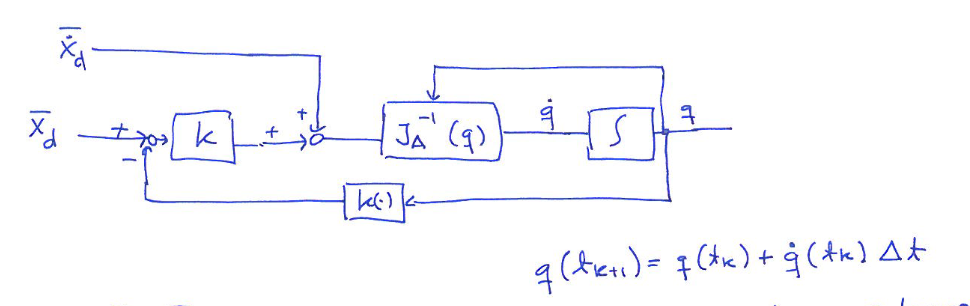

For that the function inv_kin_ps() is called and receives the loop parameters K, delta_t, initial q, desired q, A06 matrix (Direct Kinematics) and Analytical Jacobian JA matrix.

## 3) Using the Robotics Toolbox, model the manipulator as a SerialLink instance, and create a script file to verify the correctness of the functions implemented in the previous question.

### 0. Define numerical values 

In order to verify the correctness of the functions implemented in the previous question, random numerical values are definied.

q_1 = pi/5; 
q_2 = pi/4; 
q_3 = pi; 
q_4 = pi/5; 
q_5 = pi/4; 
q_6 = pi/3;
q = [q_1, q_2, q_3, q_4, q_5, q_6];

### 1. Modeling the manipulator as a SerialLink instance

% define link lenghts (meters)
a2 = 0.5;
d4 = 0.6;
d6 = 0.7; 
% define angles (radiant)
alpha1 = pi/2; 
alpha3 = pi/2; 
alpha4 = -pi/2;
alpha5 = pi/2; 

% DH paramters
L(1) = Revolute('alpha', alpha1, 'offset', pi/2);
L(2) = Revolute('a', a2);
L(3) = Revolute('alpha', alpha3, 'offset', pi/2);
L(4) = Revolute('d', d4,'alpha', alpha4);
L(5) = Revolute('alpha', alpha5, 'offset', -pi/2);
L(6) = Revolute('d', d6, 'offset', pi/2);
L;

The following code section displays the table of DH paramters with the defined offsets with help of the SerialLink.

Robot = SerialLink(L, 'name', 'MyRobot')

 
Robot = 
 
MyRobot:: 6 axis, RRRRRR, stdDH, slowRNE                         
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|     1.5708|
|  2|         q2|          0|        0.5|          0|          0|
|  3|         q3|          0|          0|     1.5708|     1.5708|
|  4|         q4|        0.6|          0|    -1.5708|          0|
|  5|         q5|          0|          0|     1.5708|    -1.5708|
|  6|         q6|        0.7|          0|          0|     1.5708|
+---+-----------+-----------+-----------+-----------+-----------+
 


Plotting the robot

Robot.plot([0,0,0,0,0,0])

### 2. Verification of the Forward Kinematics

Here the Robotics Toolbox ***.fkine()*** function is used.

A06_1 = Robot.fkine(q)

 

A06_1 = 
    0.1096   -0.9746    0.1954    0.1783
   -0.0750   -0.2041   -0.9761   -0.7404
    0.9911    0.0923   -0.0955   -0.1376
         0         0         0         1


Now the previously created function will be used to compute A06_2.

A01 = double(forward_kin(0, 0, alpha1, q_1));
A12 = double(forward_kin(a2, 0, 0, q_2));
A23 = double(forward_kin(0, 0, alpha3, q_3));
A34 = double(forward_kin(0, d4, alpha4, q_4));
A45 = double(forward_kin(0, 0, alpha5, q_5));
A56 = double(forward_kin(0, d6, 0, q_6));
A06_2 = double(A01*A12*A23*A34*A45*A56)

A06_2 =     0.8638    0.1274   -0.4875   -0.3984
   -0.4953    0.0375   -0.8679   -0.6491
   -0.0923    0.9911    0.0955    0.8447
         0         0         0    1.0000


**Result:** Both matrices **A06_1** and **A06_2** are the same, which means the function is verified.

### 3. Verfication of Geometric Jacobian

Here the Robotics Toolbox ***.jacob0()*** function is used.

J_1 = Robot.jacob0(q)

J_1 =     0.7404   -0.0809   -0.2887   -0.4449    0.2747         0
    0.1783    0.1113    0.3973   -0.0689    0.1169         0
    0.0000   -0.7039   -1.0574   -0.2057   -0.6332         0
    0.0000    0.8090    0.8090    0.4156    0.8988    0.1954
   -0.0000    0.5878    0.5878   -0.5721    0.1393   -0.9761
    1.0000    0.0000    0.0000   -0.7071    0.4156   -0.0955


Now the previously created function for the geometric jacobian is used.

z0 = [0 0 1]';
p0 = [0 0 0 1]';
J_2 = double(geometric_jacob(p0, z0, A01, A12, A23, A34, A45, A56))

J_2 =     0.6491   -0.6833   -0.3973    0.4018    0.2251    0.0000
   -0.3984   -0.4965   -0.2887   -0.2030   -0.1961   -0.0000
         0   -0.7039   -1.0574    0.2057   -0.6332         0
         0    0.5878    0.5878   -0.5721    0.8118   -0.4875
         0   -0.8090   -0.8090   -0.4156   -0.4102   -0.8679
    1.0000         0         0    0.7071    0.4156    0.0955


**Result:** The Geometric Jacobian matrices **J_1** and ***J_2*** are the same, which means that the function is verified.

### 4. Verification of Analytical Jacobian

Here the Robotics Toolbox ***.jacob0('eul')*** function is used.

JA_1 = double(Robot.jacob0(q,'eul'))

JA_1 =     0.7404   -0.0809   -0.2887   -0.4449    0.2747         0
    0.1783    0.1113    0.3973   -0.0689    0.1169         0
    0.0000   -0.7039   -1.0574   -0.2057   -0.6332         0
    1.0000   -0.0401   -0.0401   -0.6455    0.4195    0.0000
    0.0000    0.9087    0.9087    0.2952    0.9087    0.0000
    0.0000   -0.4195   -0.4195    0.6455    0.0401    1.0000


Now the previously created function for the analytical jacobian is used.

JA_2 = double(subs(JA,{q1 q2 q3 q4 q5 q6 a2 d4 d6 alpha1 alpha3 alpha4 alpha5},{q_1 q_2 q_3 q_4 q_5 q_6}));

Error using sym/subs>normalize (line 234)
Inconsistency between sizes of second and third arguments.

Error in sym/subs>mupadsubs (line 165)
[X2,Y2,symX,symY] = normalize(X,Y); %#ok

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('sym/subs', 'C:\Program Files\MATLAB\R2021b\toolbox\symbolic\symbolic\@sym\subs.m', 153)" style="font-weight:bol

**Result:** The Analytical Jacobians **JA_1** and **JA_2** are the same which means that the function is verified.

### 5. Verification of Inverse Kinematics (closed form approach)

Here the Robotics Toolbox is used.

Q1 = Robot.ikine(A06_1)

Q1 =     0.6283    0.7854    3.1416    0.6283    0.7854    1.0472


The end-effector position and orientation is obtained from the prevoius function.

vpe = A06_1.t;
vRe = A06_1.R;

Rotation matrix R03 is obtained with the substitution of the robot DH alpha parameters.

R03 = subs(R03,{alpha1 alpha3}, {alpha_1 alpha_3});

Unrecognized function or variable 'alpha_1'.

The function ***inv_kin() ***function is called to solve the inverse kinematics problem.

Q2 = inv_kin(a2, d4, d6, R03, vpe, vRe)

The fifth solution is the same as the result from the Robotics toolbox. The configuration is called **rightarm elbow up configuration.**

Now the verification of the position has to be checked.

vpe'

% robot.fkine(Q_2(1,:)).transl % Equal
% robot.fkine(Q_2(3,:)).transl % Equal
% robot.fkine(Q_2(5,:)).transl % Equal
robot.fkine(Q_2(7,:)).transl

Now the orientation is checked.

vRe

% robot.fkine(Q_2(1,:)).R % Equal
% robot.fkine(Q_2(3,:)).R % Equal
% robot.fkine(Q_2(5,:)).R % Equal
robot.fkine(Q_2(7,:)).R

Unrecognized function or variable 'Q_2'.

### 6. Verification of Inverse Kinematics (**Jacobian pseudo-inverse method/algorithm**)

First of all the Robotics Toolbox is used.

Q1_pse = Robot.ikine(A06_1)

Q1_pse =     0.6283    0.7854    3.1416    0.6283    0.7854    1.0472


Now the Direct Kinematics A06 matrix and Analytical Jacobian matrix are computed, with the substitution of the robots DH alpha parameters.

A06 = subs(A06,{a2 d4 d6 alpha1 alpha3 alpha4 alpha5},{a_2 d_4 d_6 alpha_1 alpha_3 alpha_4 alpha_5 alpha_6})

Unrecognized function or variable 'alpha_1'.

JA = subs(JA,{a2 d4 d6 alpha1 alpha3 alpha4 alpha5},{a_2 d_4 d_6 alpha_1 alpha_3 alpha_4 alpha_5 alpha_6})

The next step is to define the loop variables. The initial q vector has been chosen close enough to the desired solution in order to speed up the convergence time.

q_ini = [0.5 1 3 0.5 1 1.5];
K = 20;
delta_t = 0.05;

Calling the previously created ***inv_kin_pse()*** function.

[Q_inv_2, xd_p, xd_o] = inv_kin_pse(K, delta_t, q_ini, q, A06, JA);
Q2_pse

**Result:** Q1_pse and Q2_pse are almost the same. This is the right arm elbow up configuration.

Last but not least the verification of the position and orientation is peformed.

First the position.

xd_p'

xd_p_test = double(subs(A06(1:3,4),{q1 q2 q3 q4 q5 q6},{q(1) q(2) q(3) q(4) q(5) q(6)}));
xd_p_test'

Second the orientation.

xd_o

xd_o_test= double(subs(A06,{q1 q2 q3 q4 q5 q6},{q_1 q_2 q_3 q_4 q_5 q_6}));
Phie = xd_o_test(1:3,1:3);
phi_test = atan2(Phie(2,3),Phie(1,3));
theta_test = atan2(sqrt(Phie(1,3)^2+Phie(2,3)^2),Phie(3,3));
psi_test = atan2(Phie(3,2),-Phie(3,1));
xd_o_test = [phi_test theta_test psi_test]

## Appendix: Functions

### 2a) Forward Kinematics

The following function computes the  Forward Kinematics A matrices for all joints.

function fwk_matrix = forward_kin(a, d, alpha, q)

% Symbolic variables
syms ai di alphai qi as real
% A matrix formula
A01i = [cos(qi) -sin(qi)*cos(alphai) sin(qi)*sin(alphai) ai*cos(qi);...
sin(qi) cos(qi)*cos(alphai) -cos(qi)*sin(alphai) ai*sin(qi);...
0 sin(alphai) cos(alphai) di;...
0 0 0 1];
fwk_matrix = subs(A01i,{ai,di,alphai,qi},{ a, d, alpha, q});

end

### 2b) Geometric Jacobian

This is the function to compute the geometric jacobian. 

function J = geometric_jacob(p0, z0, A01, A12, A23, A34, A45, A56)

p1 = A01*p0;
p2 = A01*A12*p0;
p3 = A01*A12*A23*p0;
p4 = A01*A12*A23*A34*p0;
p5 = A01*A12*A23*A34*A45*p0;
p6 = A01*A12*A23*A34*A45*A56*p0;

z1 = A01(1:3,1:3)*z0;
z2 = A01(1:3,1:3)*A12(1:3,1:3)*z0;
z3 = A01(1:3,1:3)*A12(1:3,1:3)*A23(1:3,1:3)*z0;
z4 = A01(1:3,1:3)*A12(1:3,1:3)*A23(1:3,1:3)*A34(1:3,1:3)*z0;
z5 = A01(1:3,1:3)*A12(1:3,1:3)*A23(1:3,1:3)*A34(1:3,1:3)*A45(1:3,1:3)*z0;

% Geometric Jacobian
J = [cross(z0,p6(1:3)-p0(1:3)), cross(z1,p6(1:3)-p1(1:3)), cross(z2,p6(1:3)-p2(1:3)),... 
cross(z3,p6(1:3)-p3(1:3)), cross(z4,p6(1:3)-p4(1:3)), cross(z5,p6(1:3)-p5(1:3));...
            z0  z1   z2   z3  z4  z5];
end

### 2b) Analytical Jacobian

This is the function to compute the analytical jacobian. 

function JA = analytic_jacob(R, q1, q2, q3, q4, q5, q6)
% End-effector position & orientation
Pe = R(:,4);
Phie = R(1:3,1:3);

% ZYZ Euler angles
phi = atan2(Phie(2,3),Phie(1,3));
theta = atan2(sqrt(Phie(1,3)^2+Phie(2,3)^2),Phie(3,3)); 
psi = atan2(Phie(3,2),-Phie(3,1));

% Linear velocities
dPexdq1 = diff(Pe(1),q1);
dPexdq2 = diff(Pe(1),q2);
dPexdq3 = diff(Pe(1),q3);
dPexdq4 = diff(Pe(1),q4);
dPexdq5 = diff(Pe(1),q5);
dPexdq6 = diff(Pe(1),q6);

dPeydq1 = diff(Pe(2),q1);
dPeydq2 = diff(Pe(2),q2);
dPeydq3 = diff(Pe(2),q3);
dPeydq4 = diff(Pe(2),q4);
dPeydq5 = diff(Pe(2),q5);
dPeydq6 = diff(Pe(2),q6);

dPezdq1 = diff(Pe(3),q1);
dPezdq2 = diff(Pe(3),q2);
dPezdq3 = diff(Pe(3),q3);
dPezdq4 = diff(Pe(3),q4);
dPezdq5 = diff(Pe(3),q5);
dPezdq6 = diff(Pe(3),q6);

% Analytical Jacobian for linear velocities
Jp = [dPexdq1 dPexdq2 dPexdq3 dPexdq4 dPexdq5 dPexdq6;...
      dPeydq1 dPeydq2 dPeydq3 dPeydq4 dPeydq5 dPeydq6;...
      dPezdq1 dPezdq2 dPezdq3 dPezdq4 dPezdq5 dPezdq6];

% Angular velocities
dphidq1 = diff(phi,q1);
dphidq2 = diff(phi,q2);
dphidq3 = diff(phi,q3);
dphidq4 = diff(phi,q4);
dphidq5 = diff(phi,q5);
dphidq6 = diff(phi,q6);

dthetadq1 = diff(theta,q1);
dthetadq2 = diff(theta,q2);
dthetadq3 = diff(theta,q3);
dthetadq4 = diff(theta,q4);
dthetadq5 = diff(theta,q5);
dthetadq6 = diff(theta,q6);

dpsidq1 = diff(psi,q1);
dpsidq2 = diff(psi,q2);
dpsidq3 = diff(psi,q3);
dpsidq4 = diff(psi,q4);
dpsidq5 = diff(psi,q5);
dpsidq6 = diff(psi,q6);

% Analytical Jacobian for angular velocities
JPhi = [dphidq1 dphidq2 dphidq3 dphidq4 dphidq5 dphidq6;...
      dthetadq1 dthetadq2 dthetadq3 dthetadq4 dthetadq5 dthetadq6;...
      dpsidq1 dpsidq2 dpsidq3 dpsidq4 dpsidq5 dpsidq6];

% Analytical Jacobian  
JA = [Jp;JPhi];

end

### 2c) Inversed Kinematics (closed loop approach)

This is the function to compute the Inverse Kinematic using the closed loop approach.

function jointspos = inv_kin(va2, vd4, d_6, R03, vpe, vRe)

% define link lenghts
syms a2 d4 as real 
% define position end effector
syms pex pey pez as real 

% 1. Compute the wrist position pw = pe - d6*ae
% Anthropomorphic arm position of point W
pw = [pex, pey, pez]'; 
% Wrist position
vpw = vpe - d_6*vRe(:,3);

% 2. Solve inverse kinematics for Anthropomorphic arm
% Theta 3
c3 = ((pw'*pw-a2^2-d4^2)/2*a2*d4);
s3plus = sqrt(1-c3^2);
s3minus = -sqrt(1-c3^2);
theta3_I = atan2(s3plus,c3) + pi/2; % pi/2 offset added
theta3_II = atan2(s3minus,c3) + pi/2; % pi/2 offset added
% Theta 2
c2_I = ( sqrt(pw(1)^2+pw(2)^2)*(a2+d4*c3)+pw(3)*d4*s3plus )/(a2^2+d4^2+2*a2*d4*c3);
c2_II = (-sqrt(pw(1)^2+pw(2)^2)*(a2+d4*c3)+pw(3)*d4*s3plus)/(a2^2+d4^2+2*a2*d4*c3);
c2_III = ( sqrt(pw(1)^2+pw(2)^2)*(a2+d4*c3)+pw(3)*d4*s3minus )/(a2^2+d4^2+2*a2*d4*c3);
c2_IV = (-sqrt(pw(1)^2+pw(2)^2)*(a2+d4*c3)+pw(3)*d4*s3minus)/(a2^2+d4^2+2*a2*d4*c3);
s2_I = (pw(3)*(a2+d4*c3) - sqrt(pw(1)^2+pw(2)^2)*d4*s3plus)/(a2^2+d4^2+2*a2*d4*c3);
s2_II = (pw(3)*(a2+d4*c3) + sqrt(pw(1)^2+pw(2)^2)*d4*s3plus)/(a2^2+d4^2+2*a2*d4*c3);
s2_III = (pw(3)*(a2+d4*c3) - sqrt(pw(1)^2+pw(2)^2)*d4*s3minus)/(a2^2+d4^2+2*a2*d4*c3);
s2_IV = (pw(3)*(a2+d4*c3) + sqrt(pw(1)^2+pw(2)^2)*d4*s3minus)/(a2^2+d4^2+2*a2*d4*c3);
theta2_I = atan2(s2_I,c2_I);
theta2_II = atan2(s2_II,c2_II);
theta2_III = atan2(s2_III,c2_III);
theta2_IV = atan2(s2_IV,c2_IV);
% Theta 1
theta1_I = atan2(pw(2),pw(1));
theta1_II = atan2(-pw(2),-pw(1));
solspos(1,:) = [theta1_I, theta2_I, theta3_I];
solspos(2,:) = [theta1_I, theta2_III, theta3_II];
solspos(3,:) = [theta1_II, theta2_II, theta3_I];
solspos(4,:) = [theta1_II, theta2_IV, theta3_II];
% Particularize to unit link lengths
%va2 = 1.0;
%vd4 = 1.0;
vsolspos = subs(solspos,{a2 d4},{va2 vd4});
% Solution of inverse kinematics for Anthropomorphic arm
jointspos(1,1:3) = double(subs(vsolspos(1,:),{pex pey pez},{vpw(1) vpw(2) vpw(3)}));
jointspos(2,1:3) = double(subs(vsolspos(1,:),{pex pey pez},{vpw(1) vpw(2) vpw(3)}));
jointspos(3,1:3) = double(subs(vsolspos(2,:),{pex pey pez},{vpw(1) vpw(2) vpw(3)}));
jointspos(4,1:3) = double(subs(vsolspos(2,:),{pex pey pez},{vpw(1) vpw(2) vpw(3)}));
jointspos(5,1:3) = double(subs(vsolspos(3,:),{pex pey pez},{vpw(1) vpw(2) vpw(3)}));
jointspos(6,1:3) = double(subs(vsolspos(3,:),{pex pey pez},{vpw(1) vpw(2) vpw(3)}));
jointspos(7,1:3) = double(subs(vsolspos(4,:),{pex pey pez},{vpw(1) vpw(2) vpw(3)}));
jointspos(8,1:3) = double(subs(vsolspos(4,:),{pex pey pez},{vpw(1) vpw(2) vpw(3)}));

% 3.Compute R30(q1 q2 q3)
syms q1 q2 q3 as real
% Solution of inverse kinematics
q_1 = jointspos(1,:);
q_2 = jointspos(3,:);
q_3 = jointspos(5,:);
q_4 = jointspos(7,:);
% R03 matrix for each solution
vR03_1 = double(subs(R03,{q1 q2 q3}, {q_1(1) q_1(2) q_1(3)}));
vR03_2 = double(subs(R03,{q1 q2 q3}, {q_2(1) q_2(2) q_2(3)}));
vR03_3 = double(subs(R03,{q1 q2 q3}, {q_3(1) q_3(2) q_3(3)}));
vR03_4 = double(subs(R03,{q1 q2 q3}, {q_4(1) q_4(2) q_4(3)}));

% 4.Computing R63(q4 q5 q6) = R30'*Re
vR63_1 = vR03_1'*vRe;
vR63_2 = vR03_2'*vRe;
vR63_3 = vR03_3'*vRe;
vR63_4 = vR03_4'*vRe;

% 5. Solve inverse kinematics for Spherical wrist
syms nx ny nz as real
syms sx sy sz as real
syms ax ay az as real
% Rotation matrix of the spherical wrist
Re = [nx sx ax; ny sy ay; nz sz az];
n = Re(:,1);
s = Re(:,2);
a = Re(:,3);
% Theta 5
theta5_I = atan2(sqrt(a(1)^2+a(2)^2), a(3));
theta5_II = atan2(-sqrt(a(1)^2+a(2)^2), a(3));
% Theta 4
theta4_I = atan2(a(2),a(1));
theta4_II = atan2(-a(2),-a(1));
% Theta 6
theta6_I = atan2(s(3),-n(3));
theta6_II = atan2(-s(3),n(3));
% Particularized to unity lenght
vsolsori(1,:) = [theta4_I, theta5_I, theta6_I];
vsolsori(2,:) = [theta4_II, theta5_II, theta6_II];

%Final Solution
jointspos(1,4:6) = double(subs(vsolsori(1,:),{nx ny nz sx sy sz ax ay az},...
    {vR63_1(1,1) vR63_1(2,1) vR63_1(3,1) vR63_1(1,2) vR63_1(2,2) vR63_1(3,2) vR63_1(1,3) vR63_1(2,3) vR63_1(3,3)}));
jointspos(2,4:6) = double(subs(vsolsori(2,:),{nx ny nz sx sy sz ax ay az},...
    {vR63_1(1,1) vR63_1(2,1) vR63_1(3,1) vR63_1(1,2) vR63_1(2,2) vR63_1(3,2) vR63_1(1,3) vR63_1(2,3) vR63_1(3,3)}));
jointspos(3,4:6) = double(subs(vsolsori(1,:),{nx ny nz sx sy sz ax ay az},...
    {vR63_2(1,1) vR63_2(2,1) vR63_2(3,1) vR63_2(1,2) vR63_2(2,2) vR63_2(3,2) vR63_2(1,3) vR63_1(2,3) vR63_1(3,3)}));
jointspos(4,4:6) = double(subs(vsolsori(2,:),{nx ny nz sx sy sz ax ay az},...
    {vR63_2(1,1) vR63_2(2,1) vR63_2(3,1) vR63_2(1,2) vR63_2(2,2) vR63_2(3,2) vR63_2(1,3) vR63_1(2,3) vR63_1(3,3)}));
jointspos(5,4:6) = double(subs(vsolsori(1,:),{nx ny nz sx sy sz ax ay az},...
    {vR63_3(1,1) vR63_3(2,1) vR63_3(3,1) vR63_3(1,2) vR63_3(2,2) vR63_3(3,2) vR63_3(1,3) vR63_1(2,3) vR63_1(3,3)}));
jointspos(6,4:6) = double(subs(vsolsori(2,:),{nx ny nz sx sy sz ax ay az},...
    {vR63_3(1,1) vR63_3(2,1) vR63_3(3,1) vR63_3(1,2) vR63_3(2,2) vR63_3(3,2) vR63_3(1,3) vR63_1(2,3) vR63_1(3,3)}));
jointspos(7,4:6) = double(subs(vsolsori(1,:),{nx ny nz sx sy sz ax ay az},...
    {vR63_4(1,1) vR63_4(2,1) vR63_4(3,1) vR63_4(1,2) vR63_4(2,2) vR63_4(3,2) vR63_4(1,3) vR63_1(2,3) vR63_1(3,3)}));
jointspos(8,4:6) = double(subs(vsolsori(2,:),{nx ny nz sx sy sz ax ay az},...
    {vR63_4(1,1) vR63_4(2,1) vR63_4(3,1) vR63_4(1,2) vR63_4(2,2) vR63_4(3,2) vR63_4(1,3) vR63_1(2,3) vR63_1(3,3)}));
end

### 2d) Inverse Kinematics (Iterative Approach)

This is the function to compute the Inverse Kinematic using the iterative approach: **Jacobian pseudo-inverse method/algorithm**.

function [q_n, xd_p, xd_o_] = inv_kin_pse(K, delta_t, q_n, q, A06, JA)

% Define variables
syms q1 q2 q3 q4 q5 q6 as real

% Desired pose (position)
xd_p = double(subs(A06(1:3,4),{q1 q2 q3 q4 q5 q6},{q(1) q(2) q(3) q(4) q(5) q(6)}));

% Desired pose (orientation)
xd_o = double(subs(A06,{q1 q2 q3 q4 q5 q6},{q(1) q(2) q(3) q(4) q(5) q(6)}));
Phie = xd_o(1:3,1:3);
phi = atan2(Phie(2,3),Phie(1,3));
theta = atan2(sqrt(Phie(1,3)^2+Phie(2,3)^2),Phie(3,3));
psi = atan2(Phie(3,2),-Phie(3,1));
xd_o_ = [phi theta psi];

% While loop
error = 1;
iterations = 0;

while norm(error) > 0.01
    % Updating the Pose
    pos = double(subs(A06(1:3,4),{q1 q2 q3 q4 q5 q6},{q_n(1) q_n(2) q_n(3) q_n(4) q_n(5) q_n(6)}));
    pos_o = double(subs(A06,{q1 q2 q3 q4 q5 q6},{q_n(1) q_n(2) q_n(3) q_n(4) q_n(5) q_n(6)}));
    Phie = pos_o(1:3,1:3);
    phi_pos = atan2(Phie(2,3),Phie(1,3));
    theta_pos = atan2(sqrt(Phie(1,3)^2+Phie(2,3)^2),Phie(3,3));
    psi_pos = atan2(Phie(3,2),-Phie(3,1));

    % Update of Error between the desired position and the updated position
    error_p = double([xd_p(1)-pos(1), xd_p(2)-pos(2), xd_p(3)-pos(3)]);
    error_o = double([phi - phi_pos, theta - theta_pos, psi - psi_pos]);
    error = [error_p error_o]';

    % Update of Analytical Jacobian JA
    JA = double(subs(JA,{q1 q2 q3 q4 q5 q6},{q_n(1) q_n(2) q_n(3) q_n(4) q_n(5) q_n(6)}));
    
    % Computation of the new velocity
    q_dot = double(pinv(JA)*K*error);

    % Computation of the new position
    q_n = double(q_n + q_dot'*delta_t);
    
    % Next iteration step
    iterations = iterations + 1;
end
end